# Read in the RX data

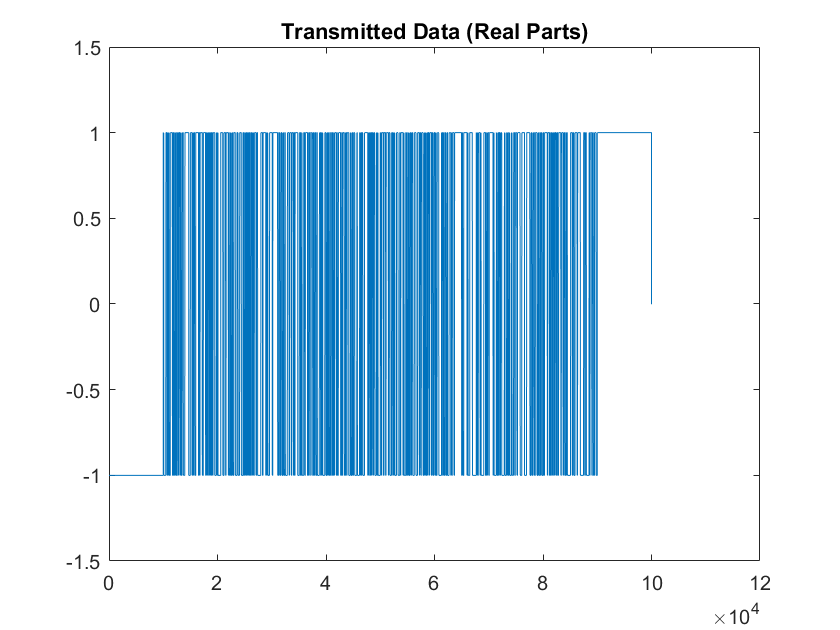

txname='tx_x7.dat';
dat=read_usrp_data_file(txname);
figure
plot(real(dat))
title('Transmitted Data (Real Parts)')
ylim([-1.5,1.5]);

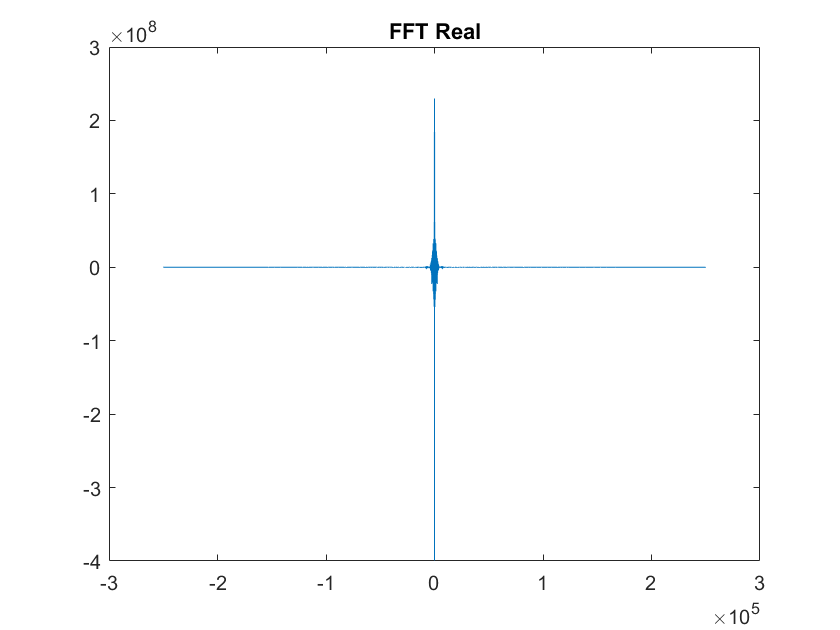

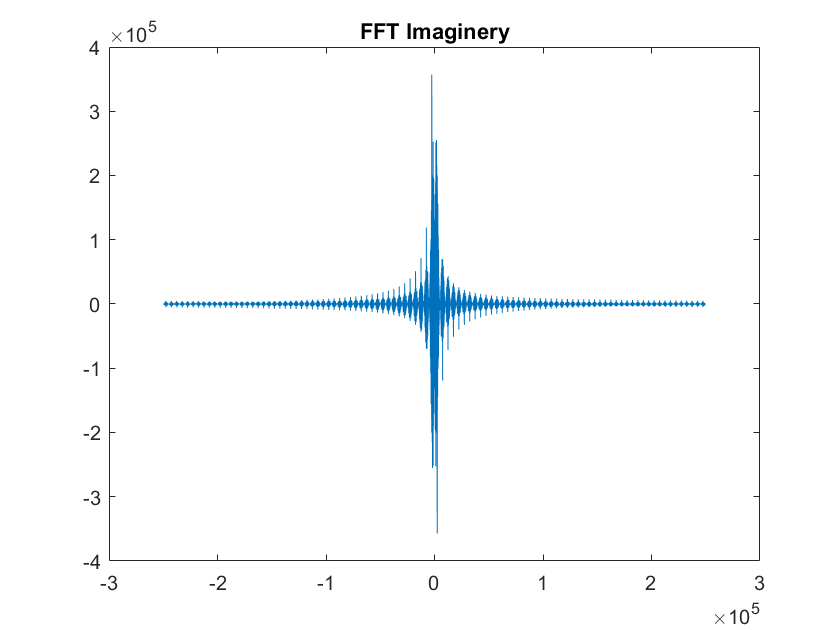

[rauto_in, lagsauto_in] = xcorr(real(dat), real(dat));
plot_FT(rauto_in, 500000);

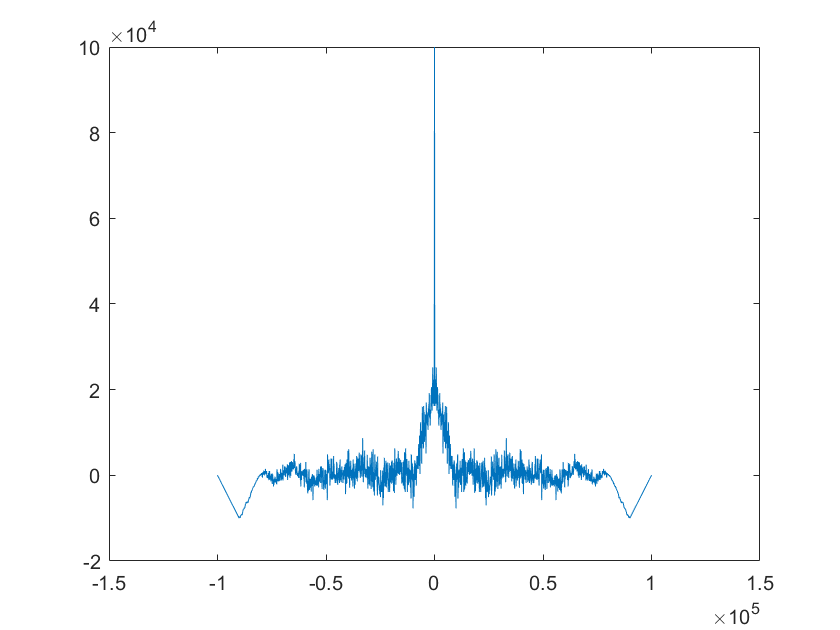

plot(lagsauto_in, rauto_in);

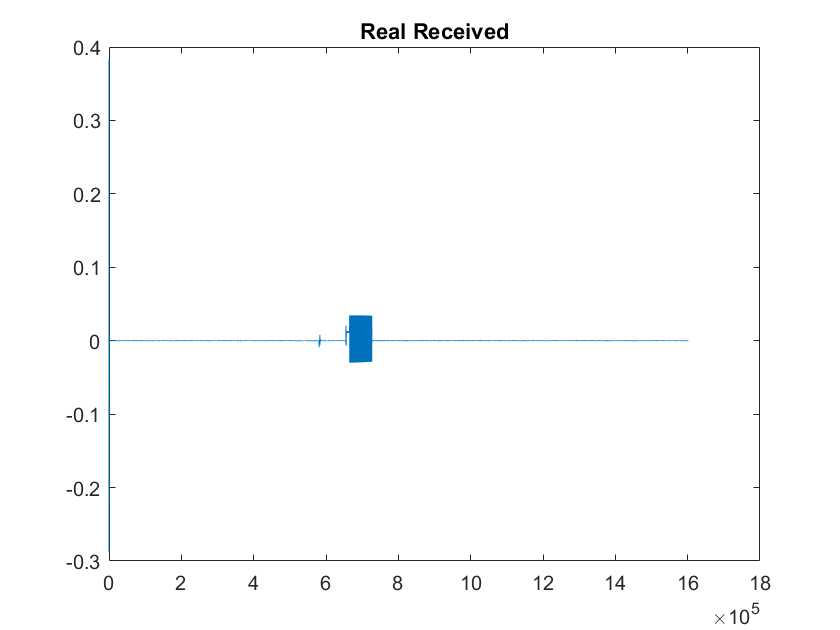

rxname='rx_x7_long.dat';
read=read_usrp_data_file(rxname);

% Plot the real and imaginery part
figure
plot(real(read))
%ylim([-1.5,1.5]);
title('Real Received')

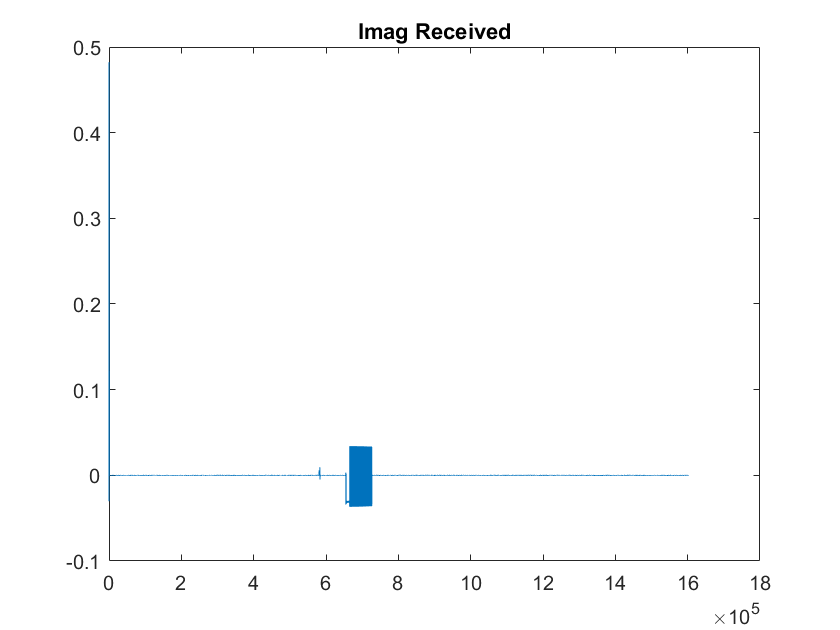

figure
plot(imag(read))
title('Imag Received')

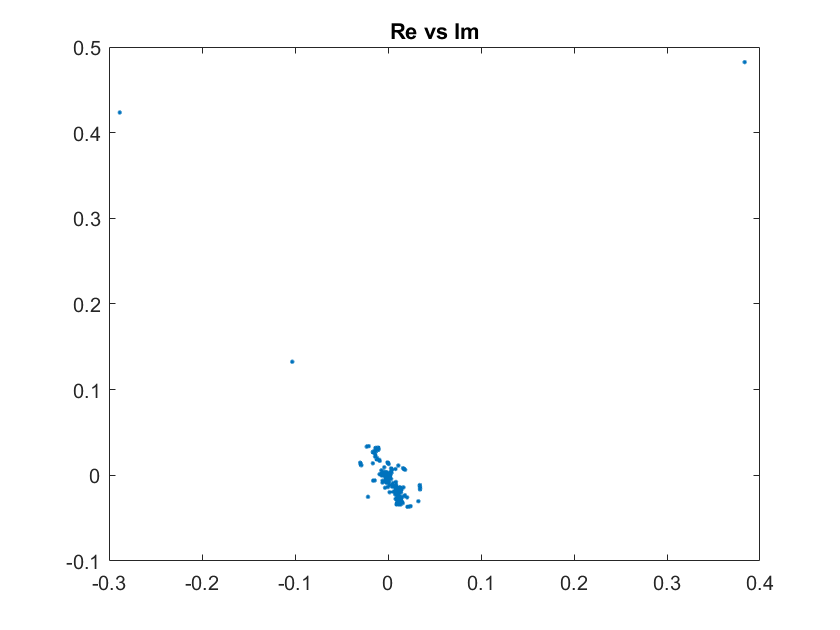


% Plot real vs imaginary
figure
plot(real(read),imag(read),'.')
title('Re vs Im')

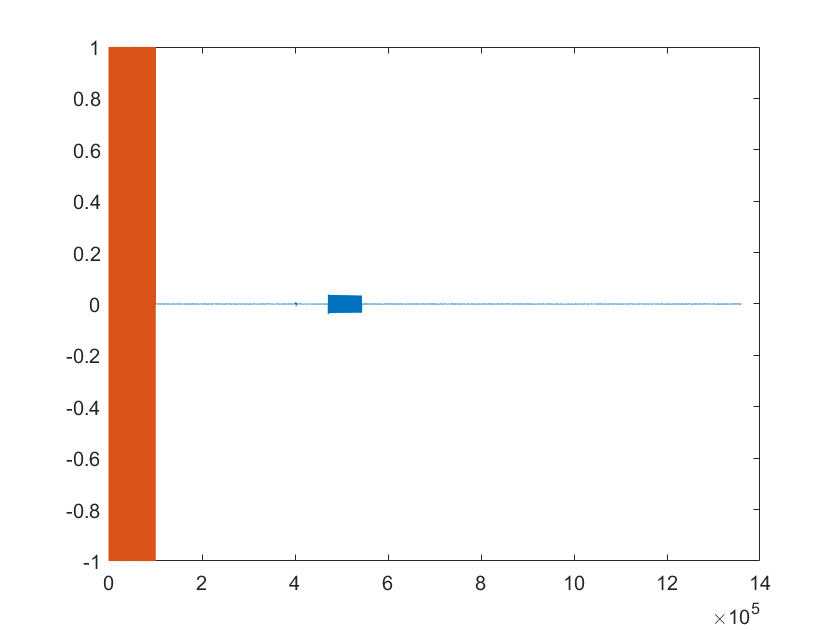

## Autocorrelate white noise

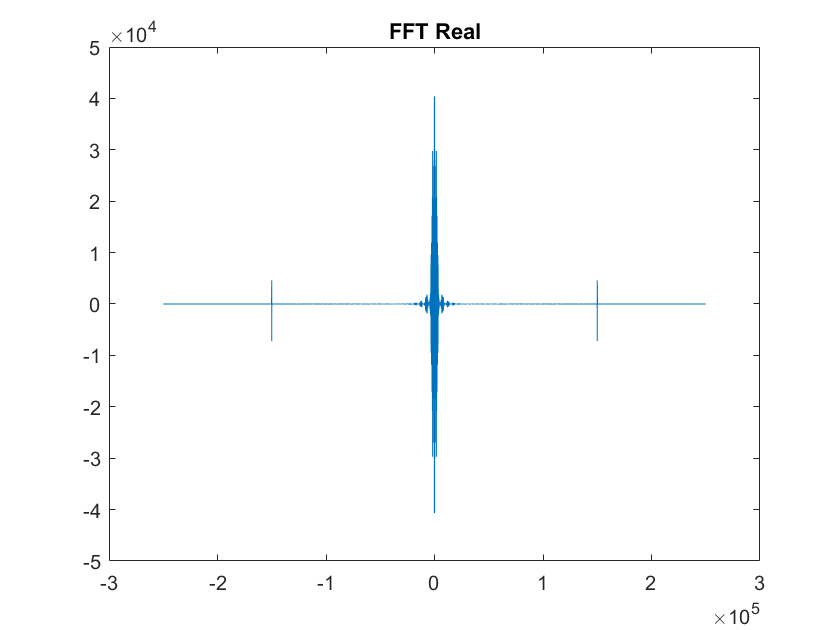

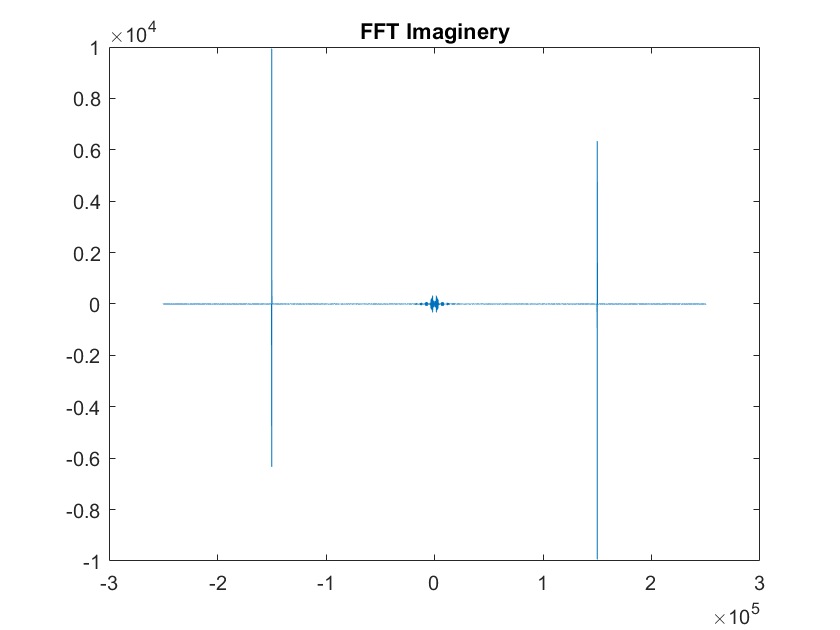

[rauto, lagsauto] = xcorr(real(read), real(read));
plot_FT(rauto, 500000);

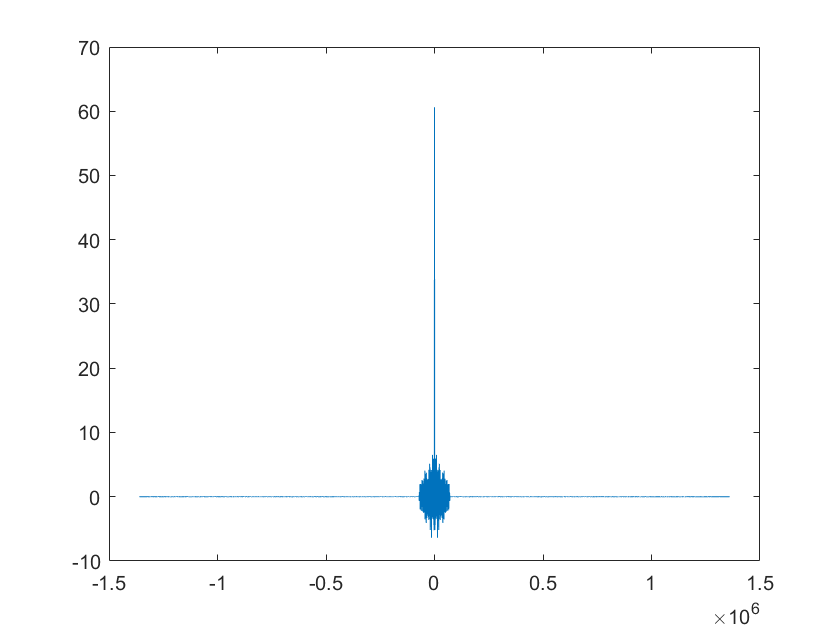

plot(lagsauto,rauto)

## Cross-correlation of the real part

[r, lags]=xcorr(real(read),real(dat));
plot(lags,abs(r))
startPos = lags(find(abs(r) == max(abs(r))))

startPos = 655486

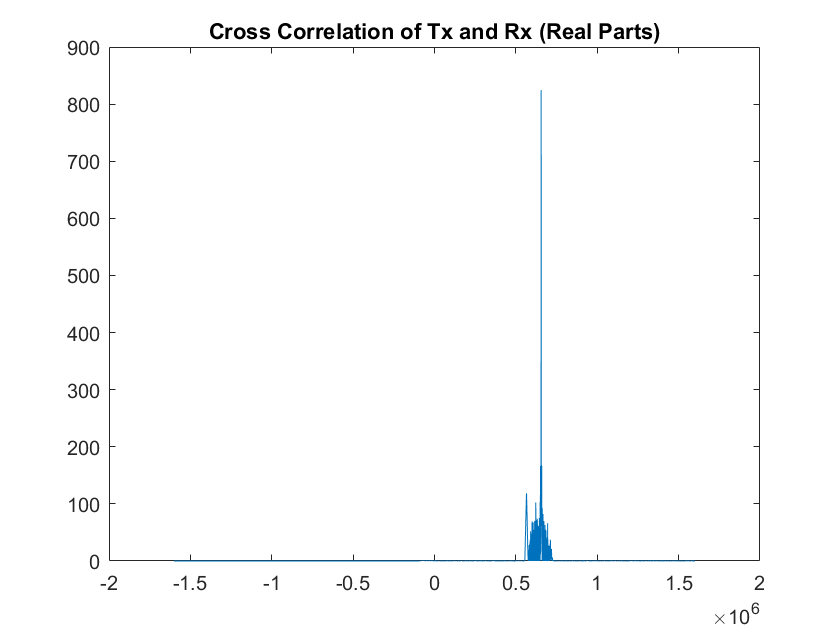

%startPos = 472100
title('Cross Correlation of Tx and Rx (Real Parts)')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

## Cross-correlation of the imaginery part

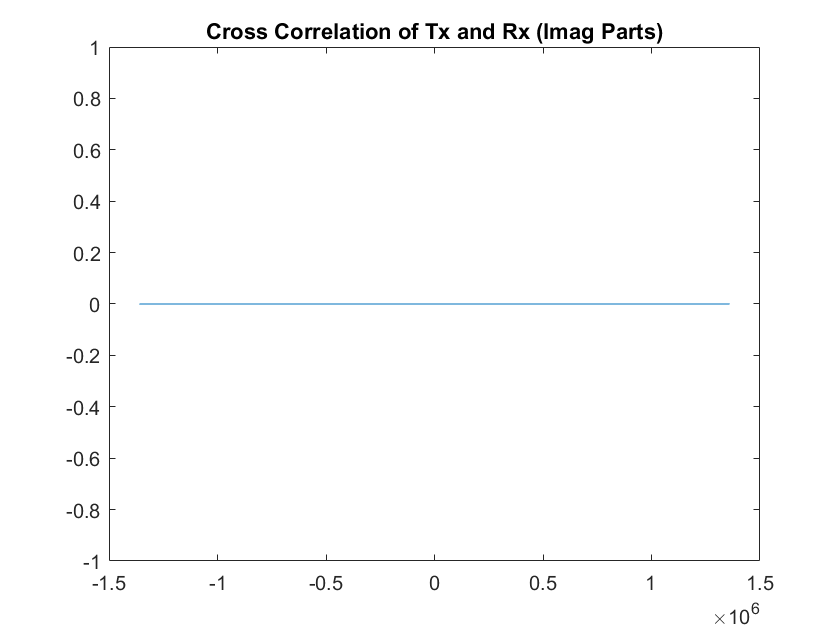

[r, lags]=xcorr(imag(read),imag(dat));
plot(lags,r)
title('Cross Correlation of Tx and Rx (Imag Parts)')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

## Error Rate Calculation

read_shifted=read(startPos:end);
%read_ds=downsample(read_shifted,100);
%data_ds = downsample(dat,100);
%signal_rx = read_ds(1:length(data_ds));
signal_rx = read_shifted(1:length(dat));
signal_rx_noise = signal_rx + sign(randn(length(signal_rx),1))*0.001;
%error=sign(real(signal_rx_noise))-sign(real(data_ds));
error=sign(real(signal_rx_noise))-real(real(dat));
err_num=length(find(error~=0));
err_rate=err_num/(length(signal_rx));
err_rate

err_rate = 0.8525

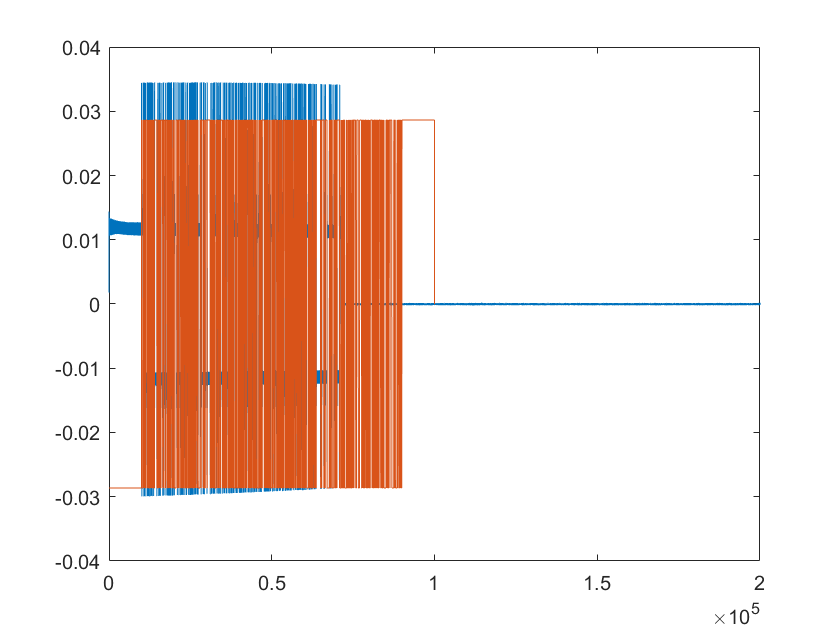

figure
plot(real(read_shifted))
ylim([-0.04,0.04])
xlim([0,2e5])
hold on;
plot(real(dat)*0.02863)
hold off;

## Attempt to adjust for phase shifting

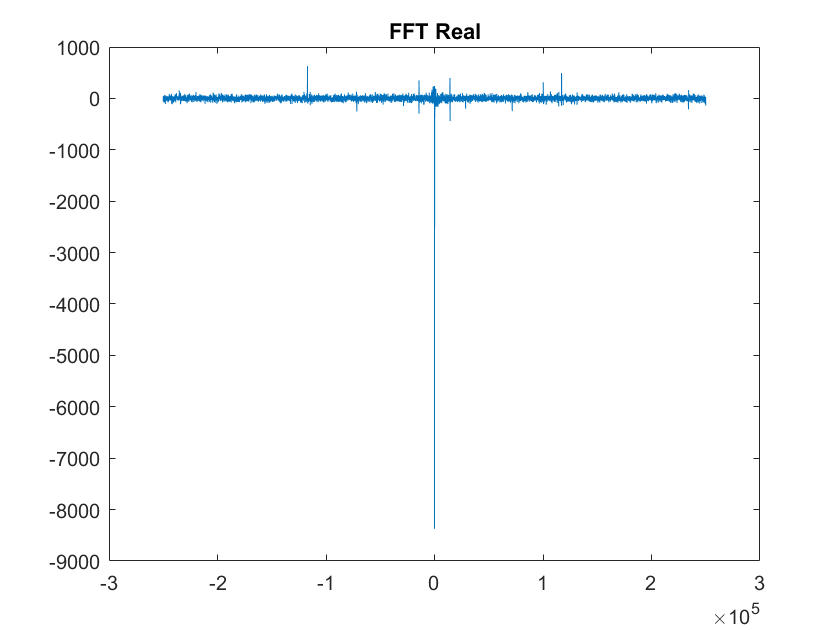

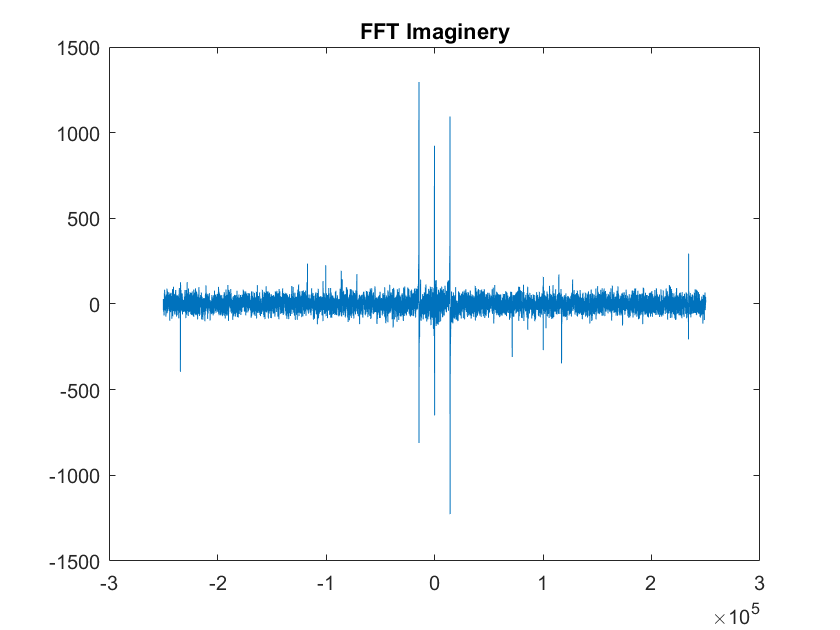

y_norm=read_ds./rms(read_ds);
y_norm_2=y_norm.^2;
plot_FT(y_norm_2, 500000);


% 2f = 200000
% 2phi = arctan(-1422497.7246/-642656);

phi=atan(6046/8322);
f=200008/2;

k=1:length(dat);
offset=exp(-1j*(f*(k-1)*1/500000+phi));
read_ds=read(153580:153580+length(dat)-1);
% read_ds=downsample(read_ds,20);
read_offset=times(read_ds,offset');

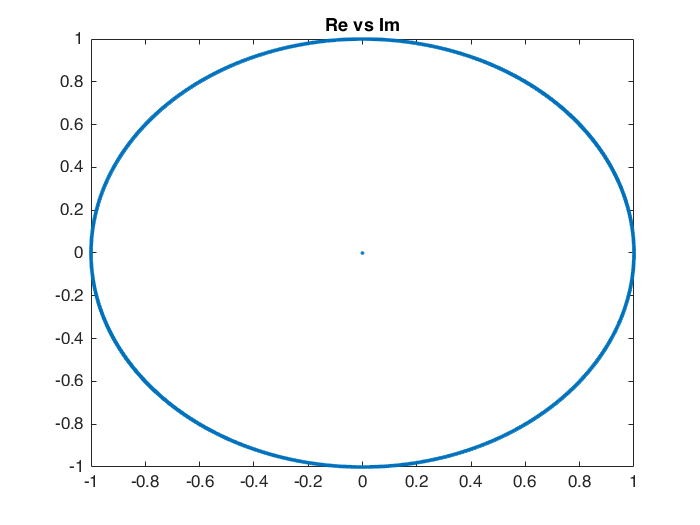


% Plot real vs imaginary
figure
plot(real(read_offset),imag(read_offset),'.')
title('Re vs Im')